# Alphavantage demonstration

## Donwload cashflow reports

% replace the "demo" apikey below with your own key from https://www.alphavantage.co/support/#api-key
keyAV = "demo";
symbols = ["TSLA","XPEV", "NIO"]; % Define symbols of interest
cashflowReports = getFundamentals(symbols, "CASH_FLOW", keyAV); % Donwload reports

1 out of 3 : TSLA
2 out of 3 : XPEV
3 out of 3 : NIO


% convert company reports to a single table
cashflowTable = extractFields(cashflowReports, ["CASH_FLOW", "quarterlyReport"]);

## Predict selected cashflow indicators

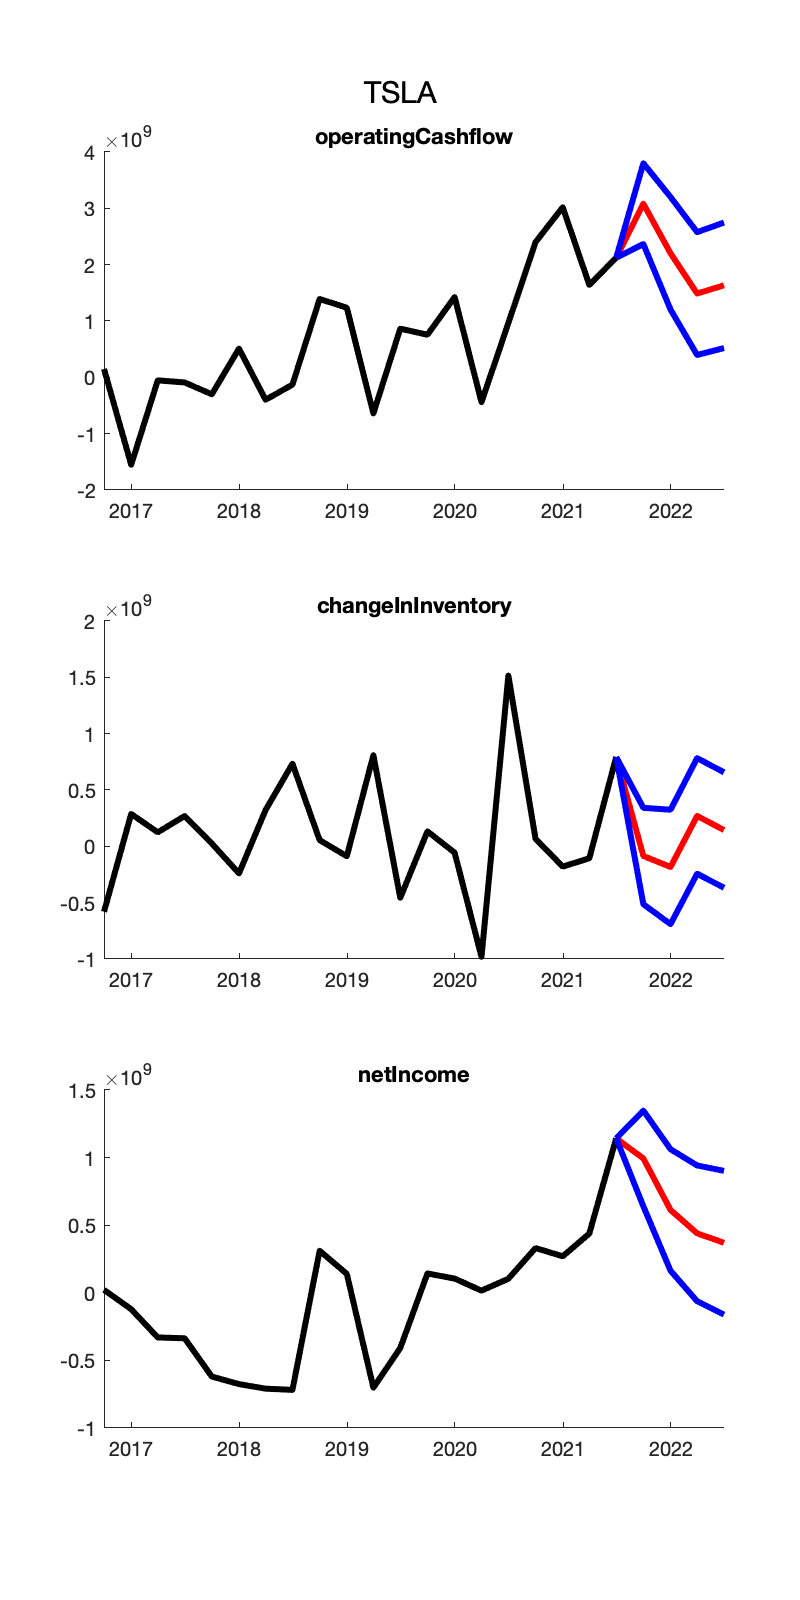

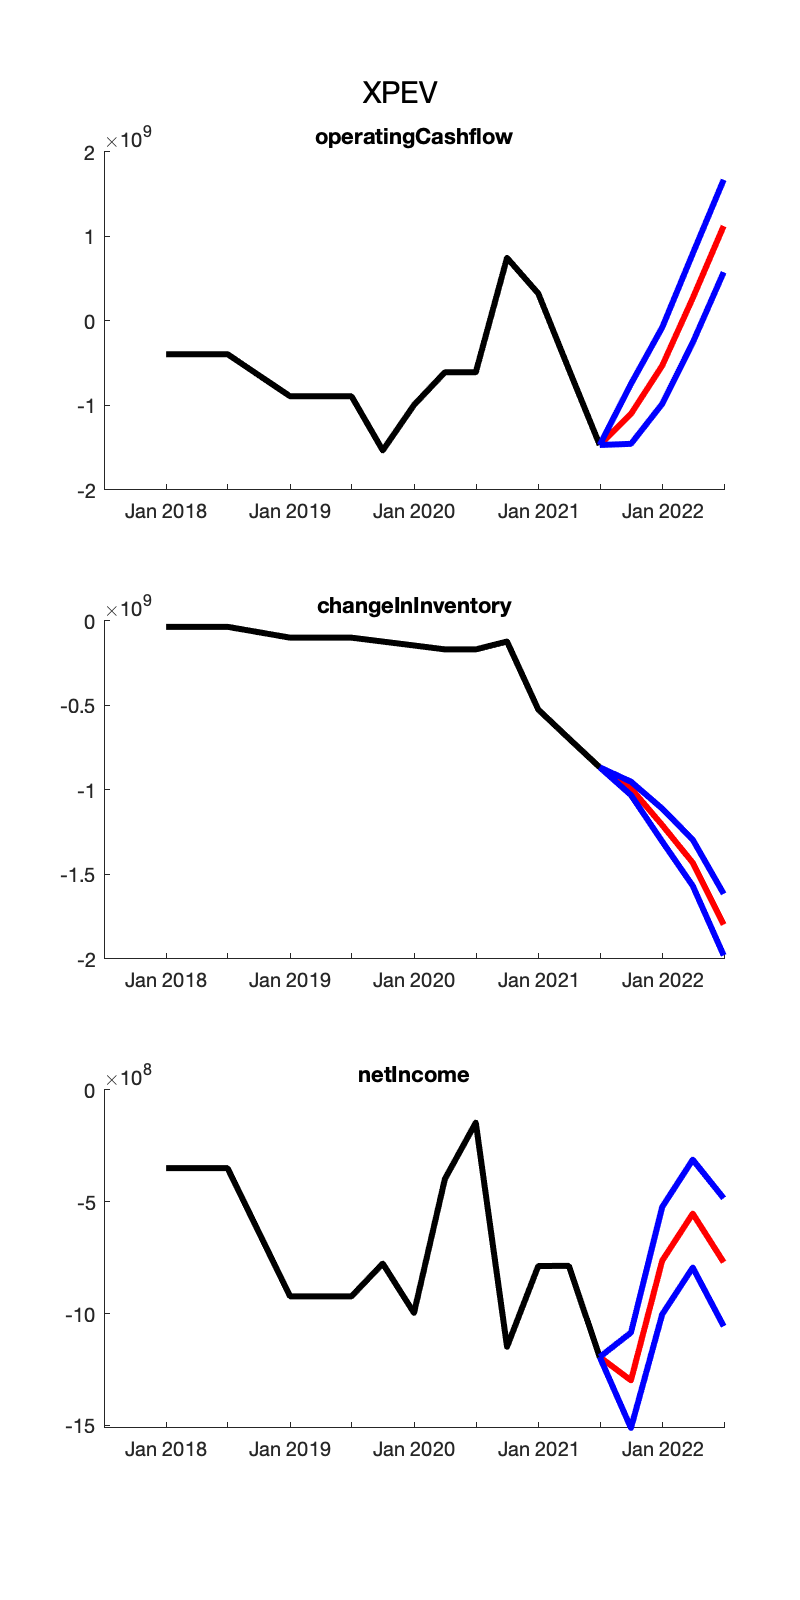

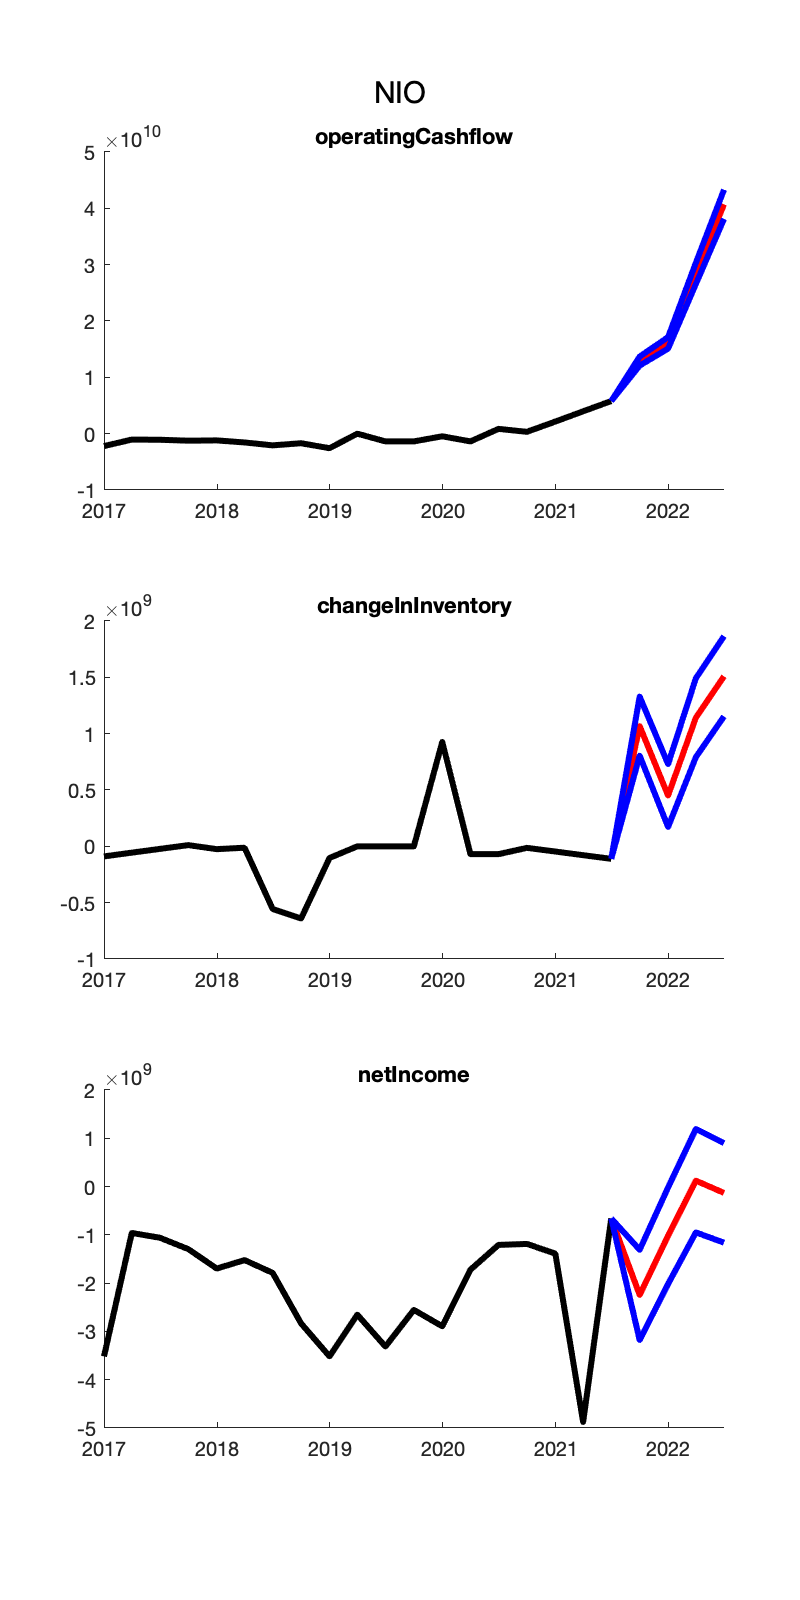

% Variables to predict
indicatorsOfInterest  = [ "operatingCashflow",...
                    "changeInInventory",...
                    "netIncome"];
    
for k = 1:length(symbols)
    % Retrieve records for a specific ticker
    reportPerCompany = findbyValue(cashflowTable, "Symbol", symbols{k});
    % preprocess 
    options = struct("extrapolate", "linear",...
                     "removeMissingBy", "column",...
                     "toCategorical", "",...
                     "removeColumns", ["reportedCurrency", "Symbol",...
                                       "proceedsFromIssuanceOfCommonStock"]);
    reportPerCompanyProcessed = preprocess(reportPerCompany, options);
    

    rawData         = reportPerCompanyProcessed(:, indicatorsOfInterest).Variables;
    Mdl             = varm(length(indicatorsOfInterest), 2);
    %Mdl.Trend       = NaN;   % Estimate trend
    [normData, means, stds] = normalize(rawData); % normalise the data
    EstMdl          = estimate(Mdl, normData);
    numOfQs          = 4;    % Forecast numOfQs quarters
    futureDates     = dateshift(reportPerCompanyProcessed.fiscalDateEnding(end)...
                            ,'end','quarter', 1:numOfQs); % Dates to predict
    
    futureSim       = simulate(EstMdl, numOfQs,'Y0', normData,'NumPaths',2000);
    futureSim       = (futureSim .*  stds) + means; % Denormalise
    futureSimMean   = mean(futureSim, 3);           % Calculate means
    futureSimStd    = std(futureSim, 0, 3);         % Calculate std deviations
    
    % Plot the predictions
    figure('color', 'white', 'position', [0, 0, 400, 800]), hold('on');
    for l = 1:length(varsOfInterest)
        subplot(length(varsOfInterest),1, l), hold on
        plot(reportPerCompanyProcessed.fiscalDateEnding, rawData(:,l),'k', 'LineWidth', 3);
        plot([reportPerCompanyProcessed.fiscalDateEnding(end) futureDates],...
                [rawData(end,l); futureSimMean(:, l)],'r', 'LineWidth', 3)
        plot([reportPerCompanyProcessed.fiscalDateEnding(end) futureDates],...
                [rawData(end,l); futureSimMean(:, l)] + [0; futureSimStd(:, l)],'b', 'LineWidth', 3)
        plot([reportPerCompanyProcessed.fiscalDateEnding(end) futureDates],...
                [rawData(end,l); futureSimMean(:, l)] - [0; futureSimStd(:, l)],'b', 'LineWidth', 3);
        title(varsOfInterest{l});
    end
    sgtitle(symbols{k});
end

## Download Economic Indicators

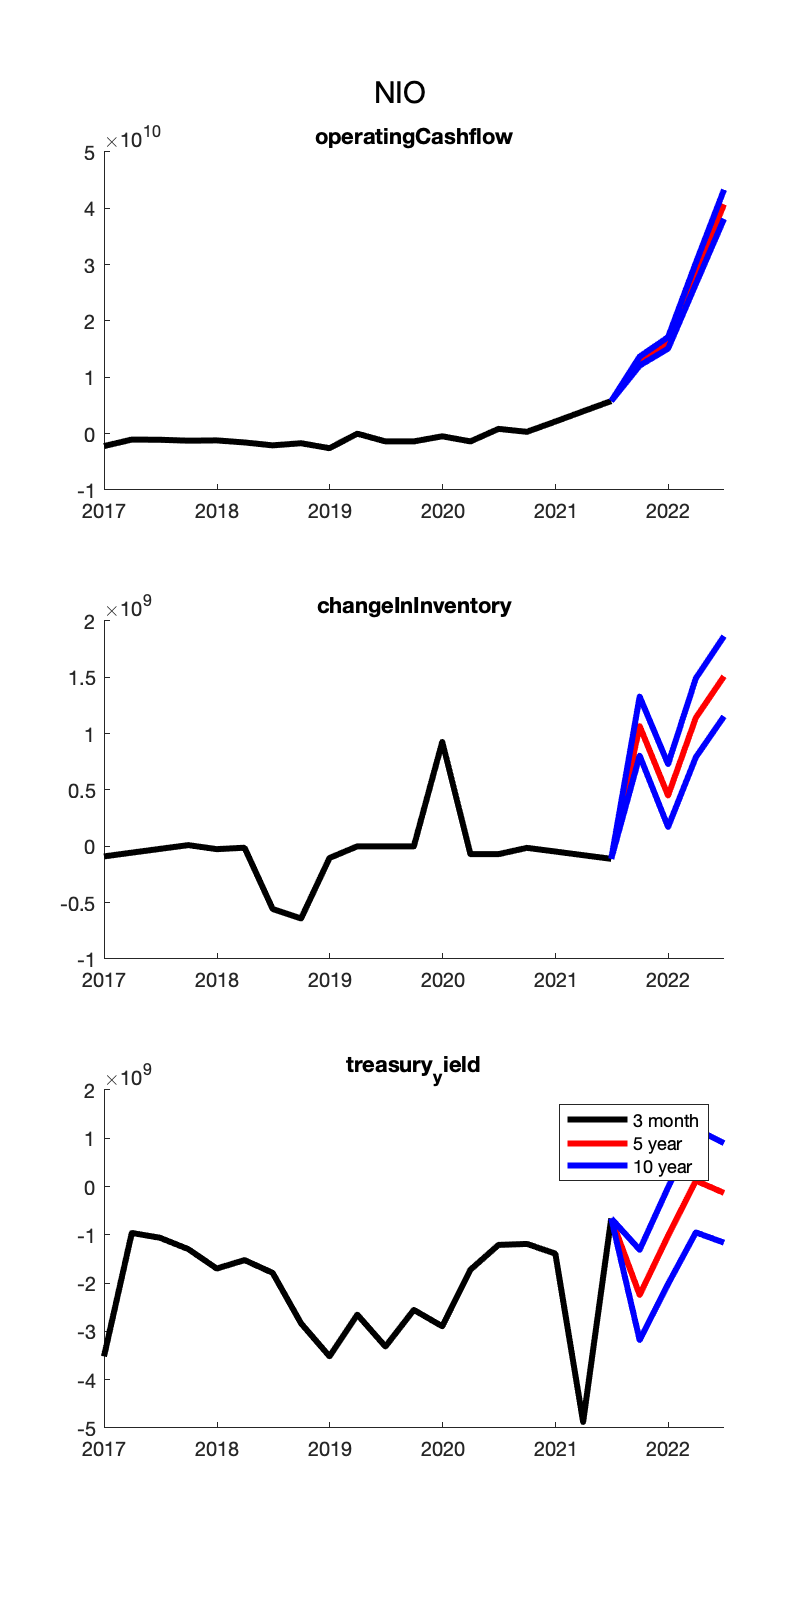

% takes time to process
treasury_yield_3month = getEconomicIndicators("TREASURY_YIELD", keyAV, struct("interval", "daily", "maturity", "3month"));
treasury_yield_5year  = getEconomicIndicators("TREASURY_YIELD", keyAV, struct("interval", "daily", "maturity", "5year"));
treasury_yield_10year = getEconomicIndicators("TREASURY_YIELD", keyAV, struct("interval", "daily", "maturity", "10year"));

## Plot economic indicators

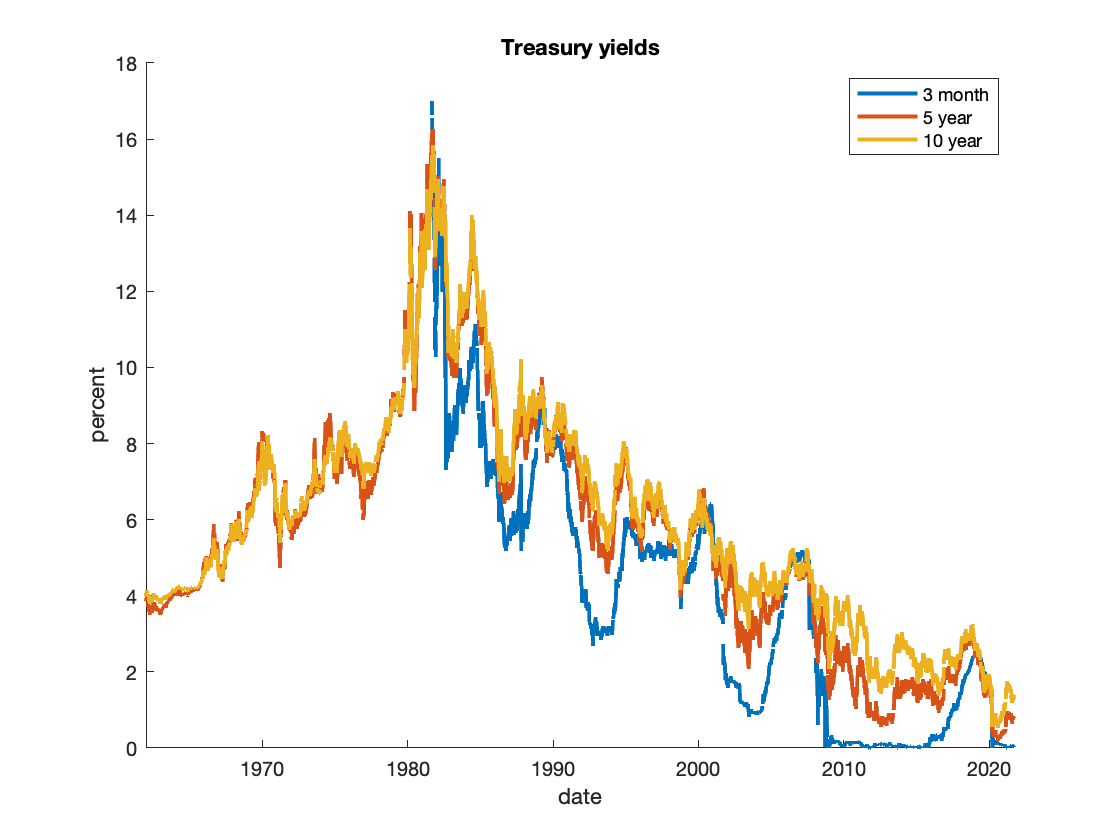

figure('color', 'white'), hold on;
plot(treasury_yield_3month.data.date,treasury_yield_3month.data.value, 'LineWidth', 2);
plot(treasury_yield_5year.data.date, treasury_yield_5year.data.value,  'LineWidth', 2);
plot(treasury_yield_10year.data.date,treasury_yield_10year.data.value, 'LineWidth', 2);
xlabel('date'), ylabel('percent');
title('Treasury yields');
legend({'3 month', '5 year', '10 year'});

## Donwload SnP500

snp500list = readtable("snp500list.csv");
load reports.mat % comment this line to donwload the data
%reports = getFundamentals(snp500list.Symbol, "ALL", keyAV); % uncomment

## Summary of SnP500

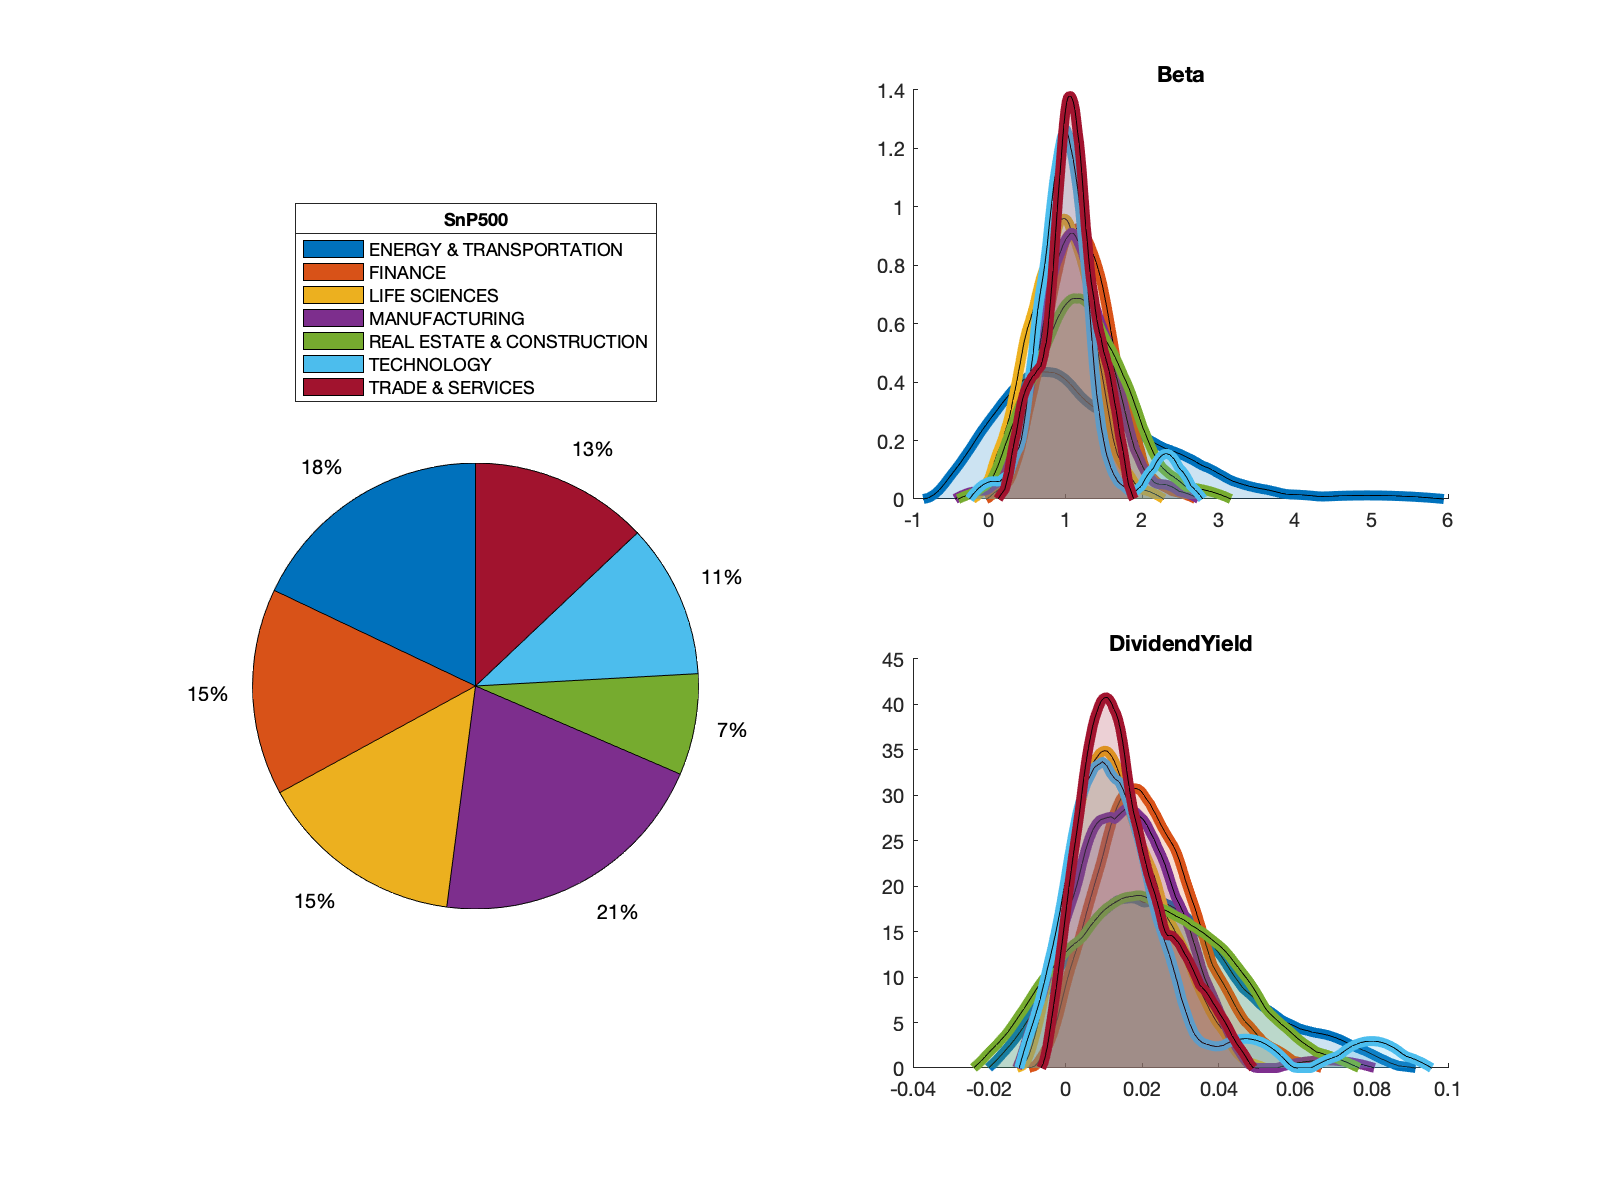

% preprocess
overviewTable = extractFields(reports, "OVERVIEW");
sectorsLabels = unique(overviewTable.Sector);
removeColumns = ["Symbol","AssetType", "Name", "Description", "Currency",...
                 "Country","Industry", "Address", "FiscalYearEnd",...
                 "LatestQuarter", "DividendDate", "ExDividendDate",...
                 "LastSplitDate"];

options = struct("extrapolate", "linear",...
                     "removeMissingBy", "row",...
                     "toCategorical", ["Exchange", "Sector"],...
                     "removeColumns", removeColumns);


[overviewTableTirm, ind] = preprocess(overviewTable, options);
sectors = unique(overviewTableTirm.Sector);


% plot pie chart 
colors = lines(length(sectorsLabels));
figure('color', 'white', 'Position', [1, 1, 800, 600]), 
p = subplot(2,2,[1,3]); pie(histcounts(overviewTableTirm.Sector));p.Colormap = lines(7);
lgnd = legend(sectorsLabels, 'Location', 'northoutside'); title(lgnd, 'SnP500');

% plot distributions of selected indicators per sector
colName = {'Beta', 'DividendYield'};
for l = 1:2
    subplot(2,2,2*l), hold on,
    for k = 1:size(sectors,1)
        overviewPerSector{k} = findbyValue(overviewTableTirm, "Sector", sectors(k));
        [m, x] = ksdensity(overviewPerSector{k}.(colName{l}),  'Kernel', 'epanechnikov'); 
        plot(x, m,'color', colors(k, :), 'linewidth', 5)
        area(x, m, 'FaceColor', colors(k, :), 'FaceAlpha', 0.2);
        title(colName{l});
    end
end